Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 9a -- Engine Data

%{
    This will be a script that will be used to complete Assignment9 
    for ME 5714 -- Digital Signal Processing.

    Sam Kramer
    April 3rd, 2023
%}

% --Setup
clear; clc; close all; format compact;

Assignment 9

Turbine Analysis

Following the assignment 9, in this assignment we’ll estimate the transfer function between the pressure transducer and the microphone data.

-  Select 10 independent vectors of the input, pressure sensor make the vector length 8192 samples. Create the corresponding vectors from the microphone data 

- Form the autospectrum for the pressure and mic data, Gxx and Gyy for the pressure and mic data respectively. Also form the cross spectrum Gxy.

- Estimate the frequency response function

- Estimate the coherence function

What are the high coherence frequencies? Any explanation?

## Part 1: Making 10 Independent Vectors of 8192 Samples

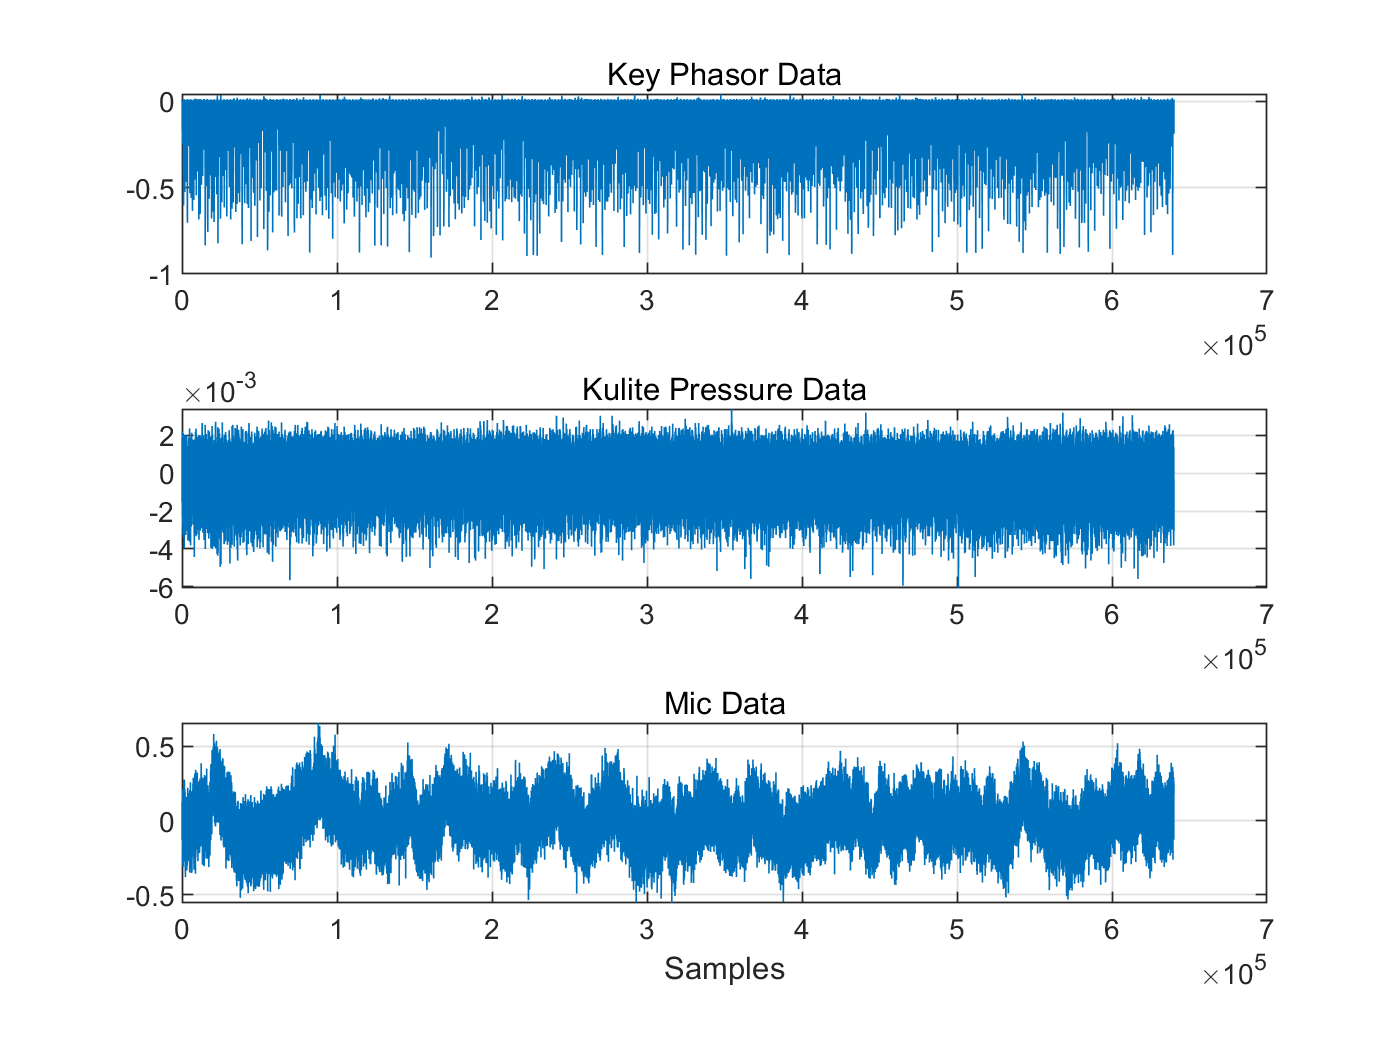

% --Load in data
    data = load('turbine data-1.mat');
    key_phasor = data.keyphasor;
    kulite_pressure = data.kulitepressure;
    mic_data = data.mic;
    
% --Zero Mean Data
    key_phasor = key_phasor - mean(key_phasor);
    kulite_pressure = kulite_pressure - mean(kulite_pressure);
    mic_data = mic_data - mean(mic_data);
    
% --Plot Data
    figure(1)
    subplot(3,1,1)
    plot(key_phasor)
        hold on
        grid on
        subtitle('Key Phasor Data')
    
    subplot(3,1,2)
    plot(kulite_pressure)
        grid on
        subtitle('Kulite Pressure Data')
    
    subplot(3,1,3)
    plot(mic_data)
        grid on
        subtitle('Mic Data')

        xlabel('Samples')
        
% --Putting pressure into data vectors
    vector_numbers = 10;
    kulite_data = [];
    data_points = 8192;         % Target Number of data points
    sample_freq = 128000;       % Sample Frequency (samples/sec)
    
    for N = 1:vector_numbers
        
        kulite_data = [kulite_data, kulite_pressure(N*data_points:(N+1)*data_points - 1, 1)];
        
    end
    
% --Putting Mic data into 10 data vectors
    vector_numbers = 10;
    mic_vectors = [];
    data_points = 8192;         % Target Number of data points
    
    for N = 1:vector_numbers
        
        mic_vectors = [mic_vectors, mic_data(N*data_points:(N+1)*data_points - 1, 1)];
        
    end

## Part 2: Autospectrums for Both Mic and Kulite Pressure Data

% --Finding the autospectrum of Kulite pressure data
    pressure_autospect = autospec(kulite_data);
    
% --Finding the autospectrum of the mic data
    mic_autospect = autospec(mic_vectors);
    
% --Format frequency
    T = data_points/sample_freq;
    freq = (1/T)*(0:(data_points - 1));
    
% --Plot autospectrums
    figure(2)
    subplot(3,1,1)
    plot(freq,pressure_autospect)
        xlim([0 max(freq)/2])
        subtitle('Autospectrum of Kulite Pressure Data (S_{xx})')
        title('Autospectrums Plots')
        ylabel('Amplitude')
        
    subplot(3,1,2)
    plot(freq,mic_autospect)
        xlim([0 length(freq)/2])
        subtitle('Autospectrum of Mic Data (S_{yy})')
        ylabel('Amplitude')
    
% --Finding Cross-spectrum
    cross_spect = crossspec(kulite_data, mic_vectors);
    
% --Plotting Cross-spectrum
    subplot(3,1,3)
    plot(freq,cross_spect)

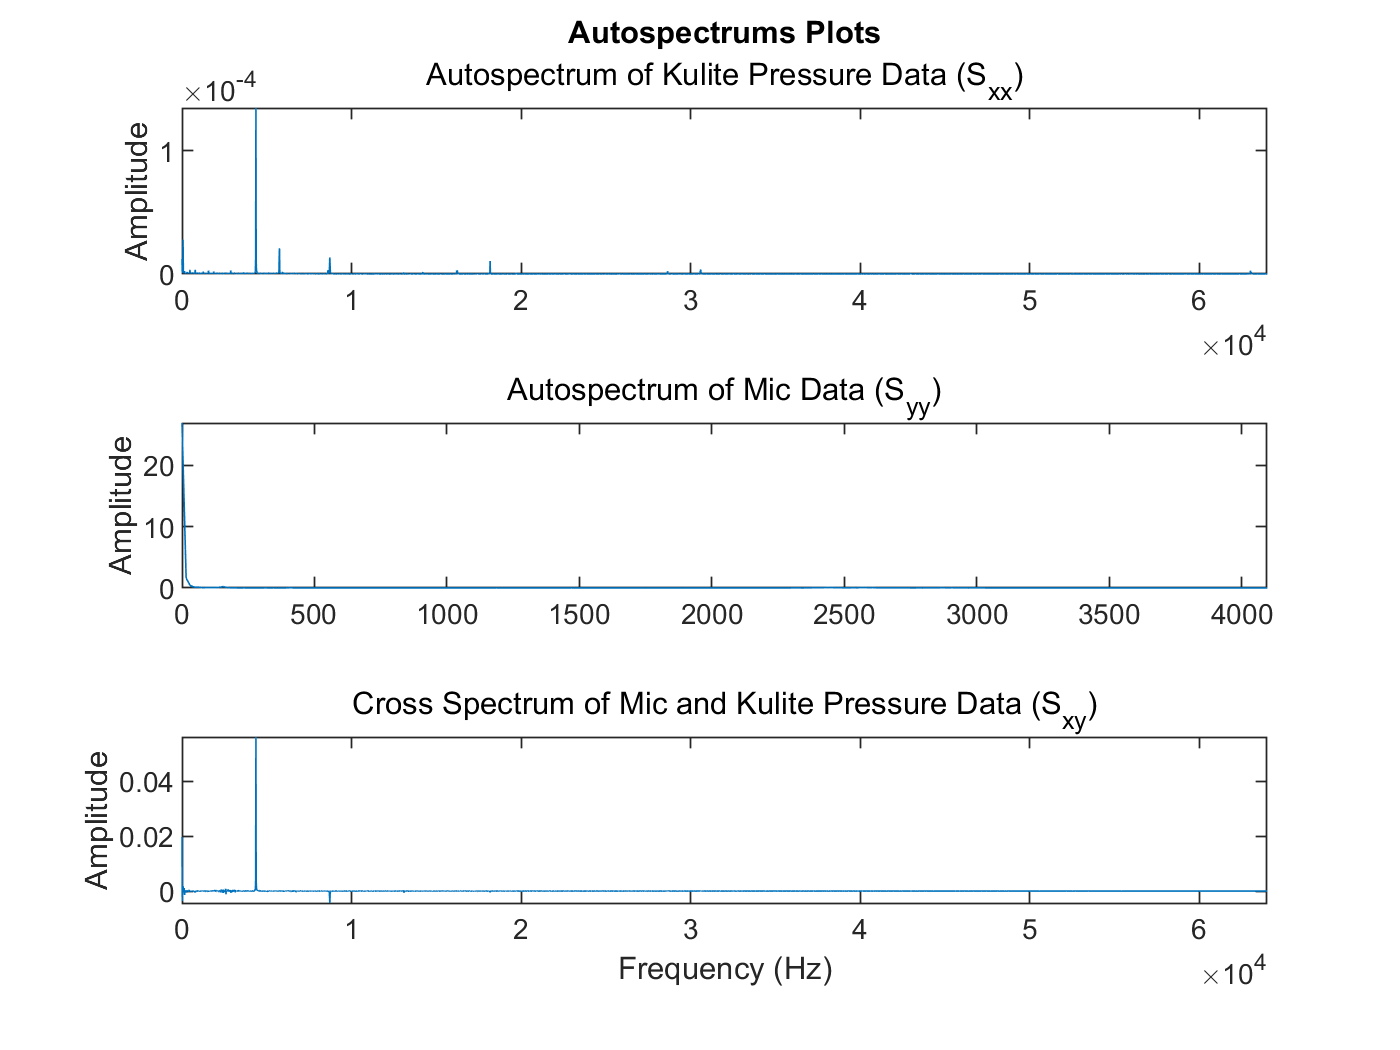

        xlabel('Frequency (Hz)')
        xlim([0 max(freq)/2])
        ylabel('Amplitude')
        subtitle('Cross Spectrum of Mic and Kulite Pressure Data (S_{xy})')

## Part 3: Frequency Response Function

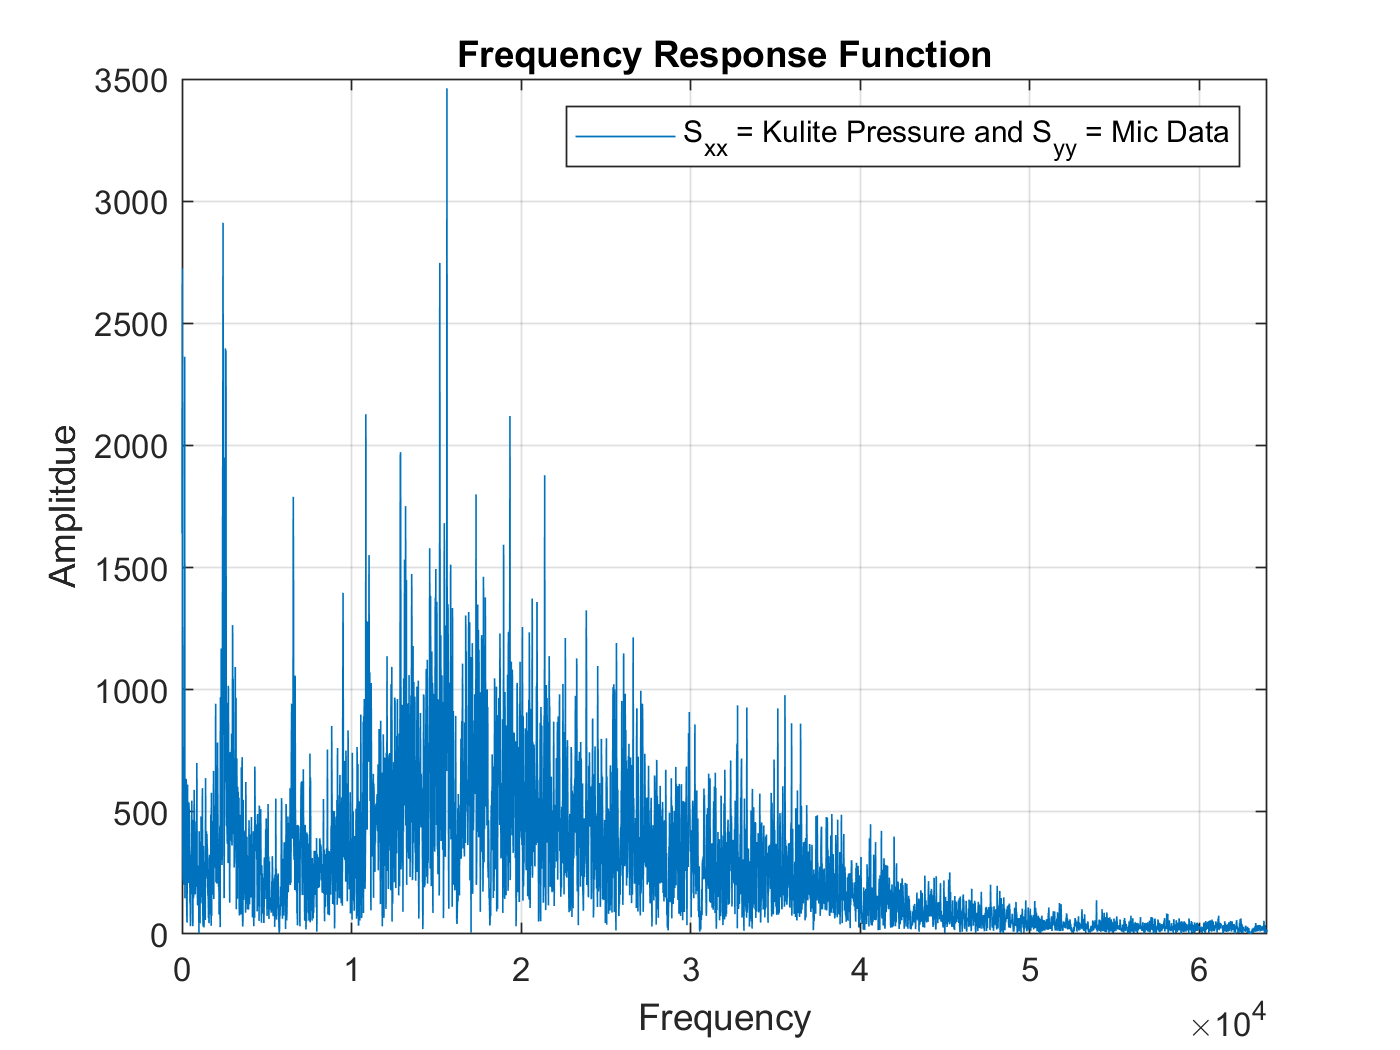

% --Calculating FRF
    FRF = abs(cross_spect) ./ pressure_autospect;
    
% --Plotting FRF of the system
    figure(3)
    plot(freq,FRF)
        hold on
        xlabel('Frequency')
        ylabel('Amplitdue')
        title('Frequency Response Function')
        xlim([0 max(freq)/2])
        grid on
        legend('S_{xx} = Kulite Pressure and S_{yy} = Mic Data')

## Part 4: Coherence Function

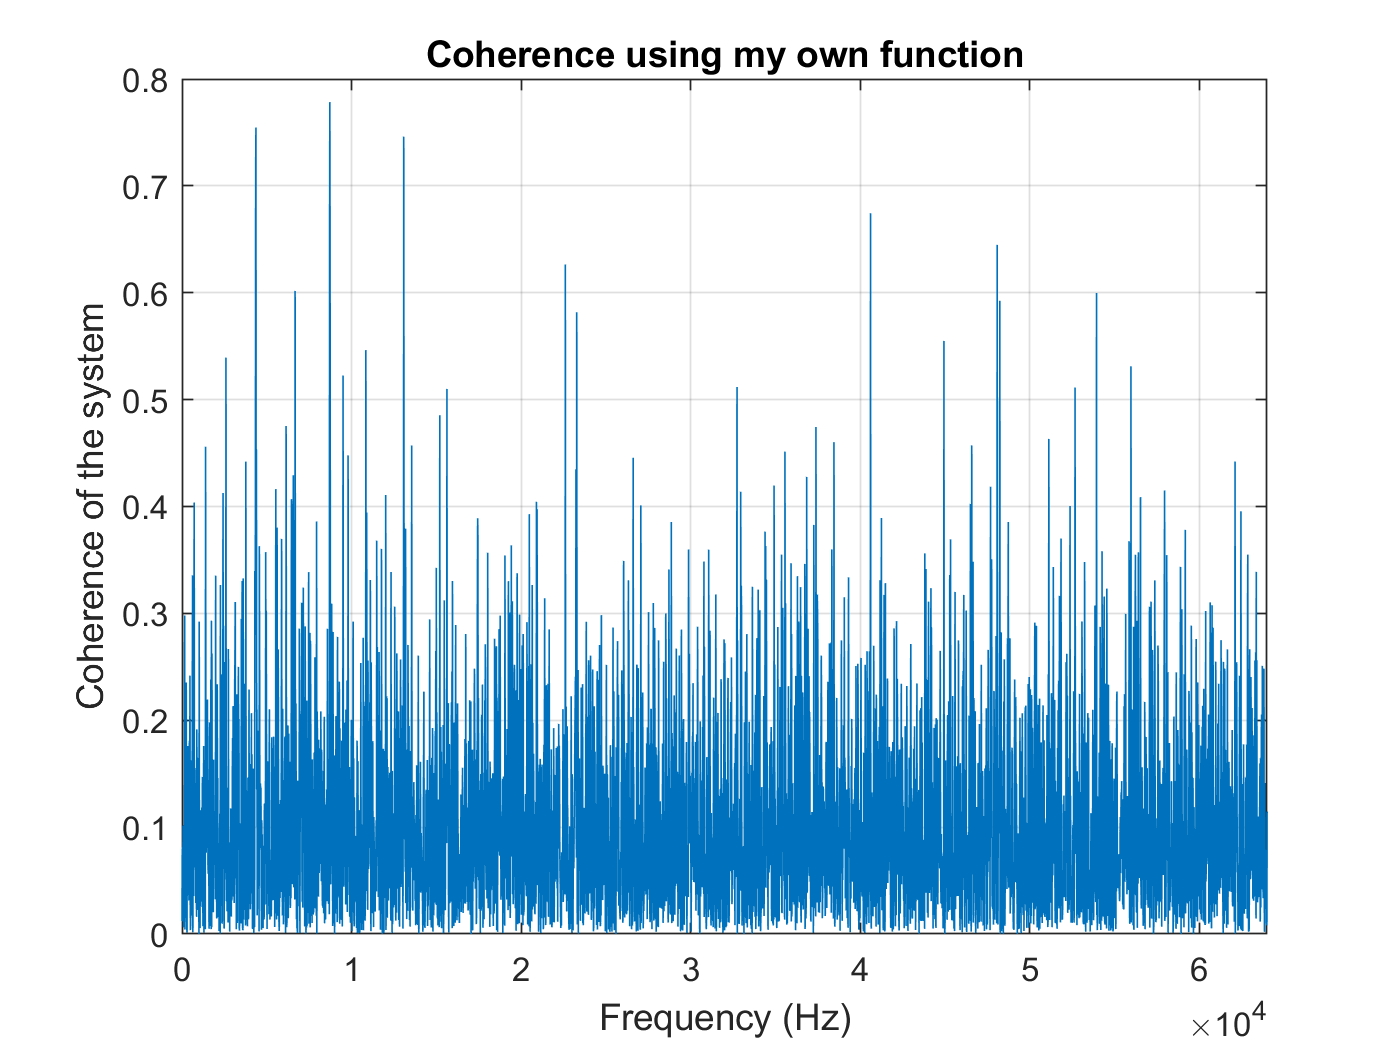

% --Calculating coherence using my own function
    gamma_squared = coherence(kulite_data, mic_vectors);
    
% --Output Coherence of data
    figure(4)
    plot(freq,gamma_squared)
        title('Coherence using my own function')
        xlabel('Frequency (Hz)')
        xlim([0 max(freq)/2])
        grid on
        hold on 
        ylabel('Coherence of the system')

        
% --Printing out the average of the coherence funciton 
    fprintf('The coherence of the signals is an average of %0.3f. \n', mean(gamma_squared))

The coherence of the signals is an average of 0.103. 


    The high coeherence frequencies appear around 1890 Hz and 578 Hz. If we look at the values of the frequency response functions, we can see that these correlate to the lowest amplitudes where the values of the autospectrum of the input is closest to the autospectrum of the output. Thus they would be close to 1 because the signals at those frequencies are very similar. From this we can see the correlated data from the frequency response function is close. 

## Functions

function auto_spect = autospec(data)
%{
    Finds autospectrum of data, data can be both a single vector and a
    matrix of multiple columns.
%}

    % --Setup
        auto_spect = zeros(length(data),1);
    
    % --Compute autospectrum of data
        for i = 1:width(data)
        
            % --Take FFT of Column data
                fftdata = fft(data(:,i));
            
            % --Find autospectrum and add it to previous value
                auto = fftdata .* conj(fftdata);
                auto = auto * 2 / (length(data)*width(data));
                auto_spect = auto_spect + auto;
        
        end
        
    % --Normalize
        auto_spect = auto_spect/ (width(data));
        
end

function cross_spect = crossspec(data1,data2)
    %{
        Performs the cross spectrum of data1 and data2 using (x*)(y) where
        x* is the complex conjugate of the fft of data1.
    %}
    
    % --Setup
        cross_spect = zeros(length(data1),1);
    
    % --Compute autospectrum of data
        for i = 1:width(data1)
        
            % --Take FFT of Column data
                fftdata1 = fft(data1(:,i));
                fftdata2 = fft(data2(:,i));
            
            % --Find cross-spectrum and add it to previous value by (X*)(Y)
                cross = conj(fftdata1) .* fftdata2;
                cross = 2 .* cross / length(data1);
                cross_spect = cross_spect + cross;
        
        end
        
    % --Normalize
        cross_spect = cross_spect / (width(data1));

end

function coherence_function = coherence(input, output)
    %{
        Finds the coherence of the data, can be multiple input or single
        output. Input size must be same as output size.
    %}

        % --Finding Gxx and etc..
            Gxx = autospec(input);
            Gyy = autospec(output);
            Gxy = crossspec(input,output);
            Gyx = crossspec(output,input);
            
        % --Compute Gamma square coherence
            gamma_squared = (abs(Gxy.*Gyx)) ./ (Gxx.*Gyy);
            gamma_squared = gamma_squared / (width(input)^2);
            
        % --Save gamma_squared
            coherence_function = (gamma_squared);
end